# **InverseJacobiNS**

[Inverse of the Jacobi elliptic function ns](https://dlmf.nist.gov/22.15)

## Definition


$${\textrm{ns}}^{-1} \left(x\left|m\right.\right)\equiv \left\lbrace \begin{array}{cc}
\mathit{\mathbf{F}}\left(x^{-1} \left|m\right.\right) & m\le 1\\
\frac{{\textrm{ns}}^{-1} \left(x\sqrt{m}\left|m^{-1} \right.\right)}{\sqrt{m}} & m>1
\end{array}\right.$$



$${\mathrm{ns}}^{-1} \left(x,k\right)\equiv {\mathrm{ns}}^{-1} \left(x\left|k^2 \right.\right)$$


where *m *is the parameter, *k *is the modulus, $\mathit{\mathbf{F}}\left(x\left|m\right.\right)$ is  the Jacobi  form of the elliptic integral of the first kind.

Domain: If $-\infty <m\le 1$ (or $|k|\le 1$) then $|x|\ge 1$. If $m>1$ (or $k>1$)  then  $\left|x\right|>\sqrt{m}$. For the specified domain, the  codomain  is the set of real numbers.

Basic features:

${\mathrm{ns}}^{-1} \left(-x\left|m\right.\right)=-{\mathrm{ns}}^{-1} \left(x\left|m\right.\right)$   (odd)

Special values:

${\mathrm{ns}}^{-1} \left(0\left|m\right.\right)=0$,   ${\textrm{ns}}^{-1} \left(\pm 1\left|m\right.\right)=\pm K\left(m\right)$

${\mathrm{ns}}^{-1} \left(x\left|-\infty \right.\right)=0$,   ${\textrm{ns}}^{-1} \left(x\left|0\right.\right)={\mathrm{csc}}^{-1} x$,   ${\textrm{ns}}^{-1} \left(x\left|1\right.\right)={\mathrm{coth}}^{-1} \left(x\right)$

Identities:


$${\mathrm{ns}}^{-1} \left(\mathrm{ns}\left(x\left|m\right.\right)\left|m\right.\right)=x,\;\;\;\;\left|x\right|<K\left(m\right)$$



$$\textrm{ns}\;\left({\mathrm{ns}}^{-1} \left(x\left|m\right.\right)\right)=x$$


$K\left(m\right)$ is the complete elliptic integral of the first kind .

## Syntax

Y = InverseJacobiNS(X,K)

y = ijns(x,k)

Y = mInverseJacobiNS(X,M)

y = mijns(x,m)

**Note. **InverseJacobiNS is equal to the function EllipticF

## Description

**Y = InverseJacobiNS(X,K)** return the Jacobi form of elliptic integral of the first kind ${\mathrm{ns}}^{-1} \left(x,k\right)$ for each element of the arrays X and K (modulus). X and K must be real and the same size or any of them can be scalar. **InverseJacobiNS** is the wrapper function which calls the functions **ijns** element-wise via the function **ufun2**.

**y = ijns(x,k)** return the value of the Jacobi form of elliptic integral of the first kind  ${\mathrm{ns}}^{-1} \left(x,k\right)$ for argument *x* and the modulus k. It is assumed that the input arguments are real scalars without check. y is NaN if any of   the input arguments is invalid or convergence failed. ijns is the wrapper function which calls the functions **mijns**.

**Y = mInverseJacobiNS(X,M)** returns the Jacobi form of elliptic integral of the first kind ${\mathrm{ns}}^{-1} \left(x\left|m\right.\right)$ for each element of the arrays X and M (parameter). X and M must be real and the same size or any of them can be scalar. **mInverseJacobiNS** is the wrapper function which calls the functions mijns element-wise via the function **ufun2**.

**y = mijns(x,m)** compute value of the Jacobi form of elliptic integral of the first kind  ${\mathrm{ns}}^{-1} \left(x\left|m\right.\right)$ for  argument x and the parameter m. It is assumed that the input arguments are real scalars without check. y is NaN if any of  the input arguments is invalid or convergence failed.  **mijns **call the Carlson's function **rf **for calculation of ${\mathrm{ns}}^{-1} \left(x\left|m\right.\right)$ ([1-2]).

## Precision

## **Numerical Examples**

**Scalar input**

format long
k = 0.5;
x = 1.5;
[ijns(x,k), InverseJacobiNS(x,k), mijns(x,k^2), mInverseJacobiNS(x,k^2)]

ans =    0.745086378712953   0.745086378712953   0.745086378712953   0.745086378712953


% Maple 0.745086378712953_226

Accuracy.

fprintf('%.16g\n',mijns(1.5,-4)) 

0.5935198101824097


%  Maple 0.5935198101824098_75

Special values

m = -2;
x = 1.5;  % |x| >= 1
disp(mijns(1,m) - melK(m))  % m < 1 !!!

     0



disp(mijns(-1,m) + melK(m))  % m < 1 !!!

     0



mijns(x,-inf)

ans = 0

disp(mijns(x,0) - acsc(x)) 

     0



disp(mijns(x,1) - acoth(x))

     0



mijns(x,inf)  % x = 0

ans = 0

Identities


m = 2; % m>1
x = 2; % x > sqrt(m)
disp(mijns(x,m)-mijns(x/sqrt(m),1/m)/sqrt(m))

     0



**Vector input**

k = [0.1, 0.5, 0.89, 0.99995];
x  = 2;
disp(InverseJacobiNS(x,k)-InverseJacobiNS(x./k,1./k)./k)

   1.0e-15 *

   0.111022302462516  -0.111022302462516   0.111022302462516   0.222044604925031



**Matrix input**

k = [0.1, 0.5, 0.89; -0.1, -0.97, 0.99995 ]';
x  = 2*ones(size(k));
disp(InverseJacobiNS(x,k)-InverseJacobiNS(x./k,1./k)./k)

   1.0e-15 *

   0.111022302462516   0.111022302462516
  -0.111022302462516                   0
   0.111022302462516   0.222044604925031



## **Plot **

**Example 1**

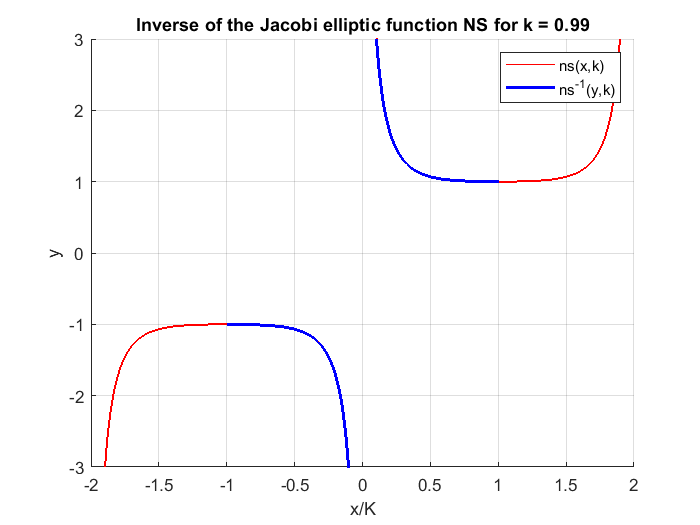

figure
hold on
x=-2:0.01:2;
k = 0.99;
K = elK(k);
plot(x,JacobiNS(K*x,k),'LineWidth',1.0,'Color','red')
x=-12:0.01:12;
plot(InverseJacobiNS(x,k)/K,x,'LineWidth',2,'Color','blue')
legend('ns(x,k)','ns^{-1}(y,k)') %,'Position','best')
xlabel('x/K')
ylabel('y')
%xlim([-1.1 1.1])
ylim([-3 3])
title(sprintf('Inverse of the Jacobi elliptic function NS for k = %g',k))
grid on
hold off

**Example 2**

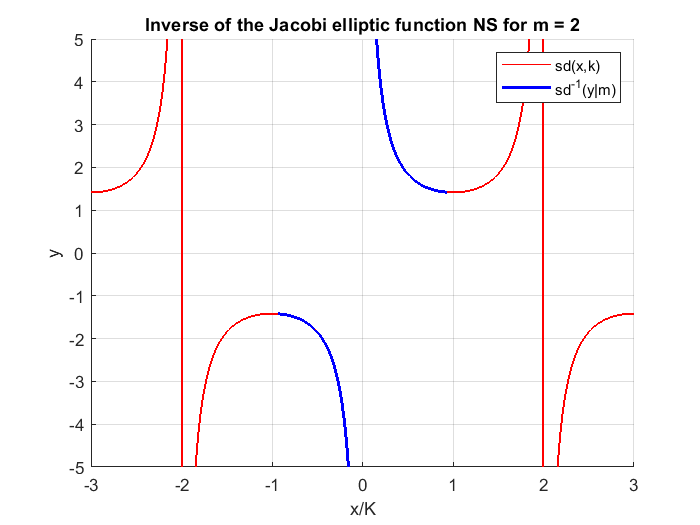

figure
hold on
x=-3:0.01:3;
m = 2;
if m < 1
    M = melK(m);
    xlabel('x/K')
elseif m > 1
    M = melK(1/m)/sqrt(m);
    xlabel('x/K')
else
    M = 1;
    xlabel('x')
end
plot(x,mJacobiNS(M*x,m),'LineWidth',1.0,'Color','red')
x=-102:0.01:102;
plot(mInverseJacobiNS(x,m)/M,x,'LineWidth',2,'Color','blue')
legend('sd(x,k)','sd^{-1}(y|m)') %,'Position','best')
ylabel('y')
%xlim([-1.1 1.1])
ylim([-5 5])
title(sprintf('Inverse of the Jacobi elliptic function NS for m = %g',m))
grid on
hold off

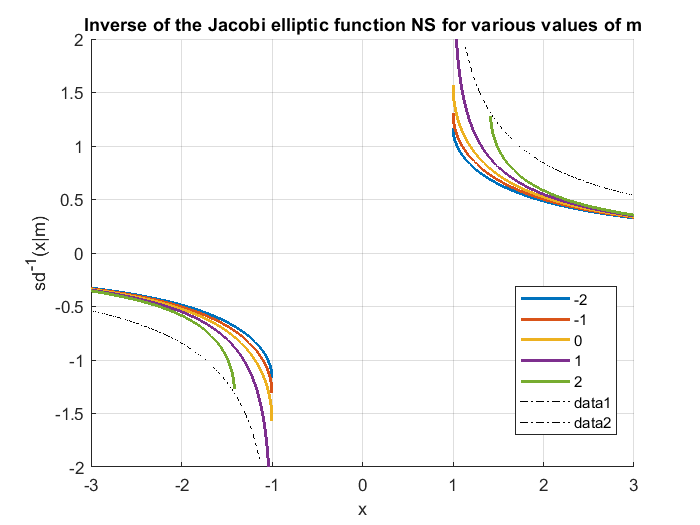

figure
hold on
X = -3:0.001:3;
M = [-2,-1,0,1,2];
SN = zeros(length(M),length(X));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mInverseJacobiNS(X,M(i));
end
plot(X,SN,'LineWidth',1.5)
axis([min(X) max(X) -2 2])
grid on
legend(clg{1:length(M)},'Location','Best')
title('Inverse of the Jacobi elliptic function NS for various values of m')
N=1:0.01:10;
X = sqrt(N);
plot(X,mInverseJacobiNS(X,N),'k-.')
plot(-X,-mInverseJacobiNS(X,N),'k-.')
xlabel('x')
ylabel('sd^{-1}(x|m)')

**Example 4**

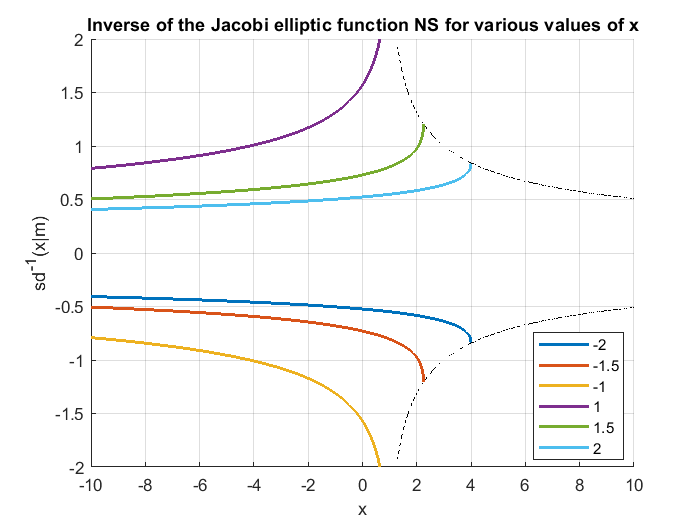

figure
hold on
M = -10:0.01:10;
X = [-2,-1.5,-1,1,1.5,2];
SN = zeros(length(X),length(M));
clg{length(X)}=[];
for i = 1:length(X)
     clg{i} = num2str(X(i));
    SN(i,:) = mInverseJacobiNS(X(i),M);
end
plot(M,SN,'LineWidth',1.5)
axis([min(M) max(M) -3 3])
ylim([-2  2])
grid on
legend(clg{1:length(X)},'Location','Best')
title('Inverse of the Jacobi elliptic function NS for various values of x')
xlabel('x')
ylabel('sd^{-1}(x|m)')
M = 1:0.01:10;
F = mInverseJacobiNS(sqrt(M),M);
plot(M,F,'k-.')
plot(M,-F,'k-.')
hold off

**Example 5**

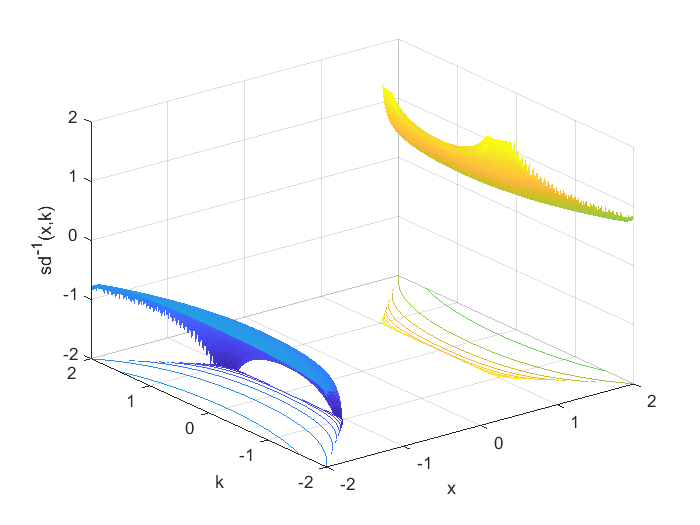

figure
x=-2:0.01:2;
k=-2:0.01:2;
zz = 2;
[X,M]=meshgrid(x,k);
hs=surfc(X,M,InverseJacobiNS(X,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -zz;
hc.LineWidth = 0.5;
hc.LevelList = -zz:zz/10:zz;
view(3)
caxis([-zz zz])
xlabel('x')
ylabel('k')
zlabel('sd^{-1}(x,k)')
zlim([-zz zz])
grid on

**Example 6**

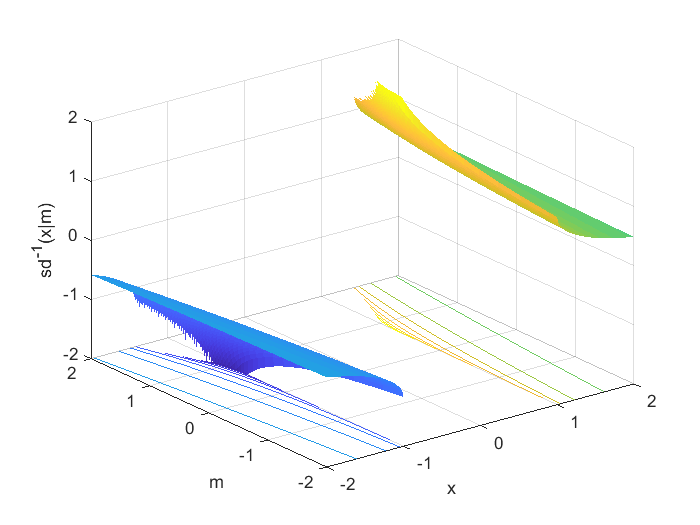

figure
x=-2:0.01:2;
m=-2:0.01:2;
zz = 2;
[X,M]=meshgrid(x,m);
hs=surfc(X,M,mInverseJacobiNS(X,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -zz;
hc.LineWidth = 0.5;
hc.LevelList = -zz:zz/10:zz;
view(3)
caxis([-zz zz])
xlabel('x')
ylabel('m')
zlabel('sd^{-1}(x|m)')
zlim([-zz zz])
grid on

**Example 7**

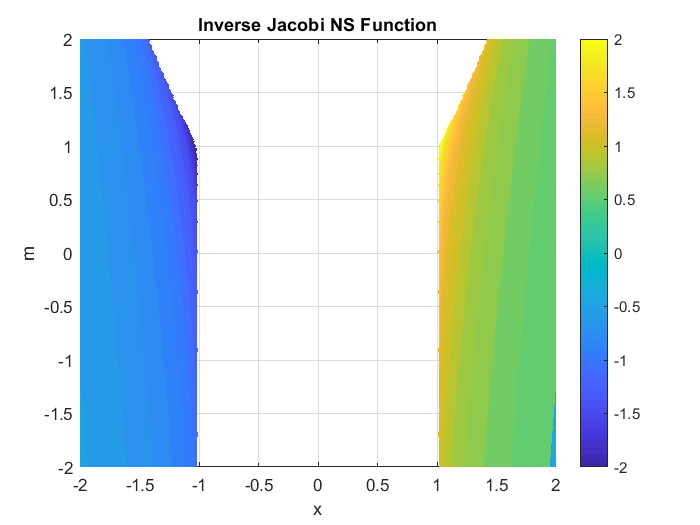

figure
f = @(x,m)mInverseJacobiNS(x,m);
fcontour(f,[-2 2 -2 2],'Fill','on','LevelList',-2:0.1:2,'MeshDensity',200)
title('Inverse Jacobi NS Function')
colorbar
xlabel('x')
ylabel('m')
grid on

**Example 8**

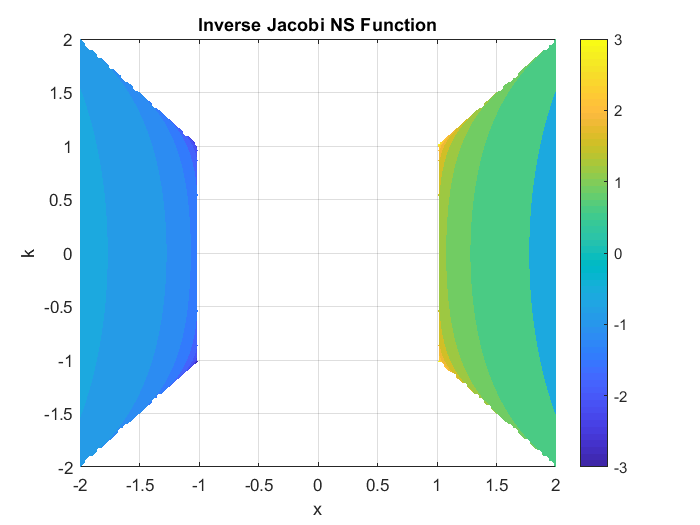

figure
f = @(x,k)InverseJacobiNS(x,k);
fcontour(f,[-2 2 -2 2],'Fill','on','LevelList',-3:0.3:3,'MeshDensity',200)
title('Inverse Jacobi NS Function')
colorbar
xlabel('x')
ylabel('k')
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Jacobian Elliptic Functions, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/22)

[Jacobi elliptic functions, Wikipedia](https://en.wikipedia.org/wiki/Jacobi_elliptic_functions)

## **References**

[1] B.C. Carlson, Computing Elliptic Integrals by Duplication. Numerische Mathematik 33, 1-16, 1979.

[2] W.H. Press et al., Numerical Recipes, 3rd ed., Cambridge, 2007

## See Also